Lab6 

## Confidence intervals

For this week we will be using the real data you are working on, but more as a background for the main activity rather than in depth explorations. Don't worry, more in-depth exploration the next two weeks!

**Setup**

First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files.  

LHC

For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. 

bg = makedist('Poisson','lambda',100);

**Problem 1**

The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

Calculating signal from sigma:

sig = 5;
p_calcd = normcdf(sig)

p_calcd =    0.999999713348428


signal_5 = icdf(bg,p_calcd)

signal_5 =    154


**Problem 2**

Now inject a signal of known strength. You will want to make your signal moderately strong, say somewhere in the 8-30σσ range. Inject this signal into your background data many times.

a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

sig = 14;
p_calcd = normcdf(sig)

p_calcd =      1


signal_14 = icdf(bg,p_calcd)

signal_14 =    Inf


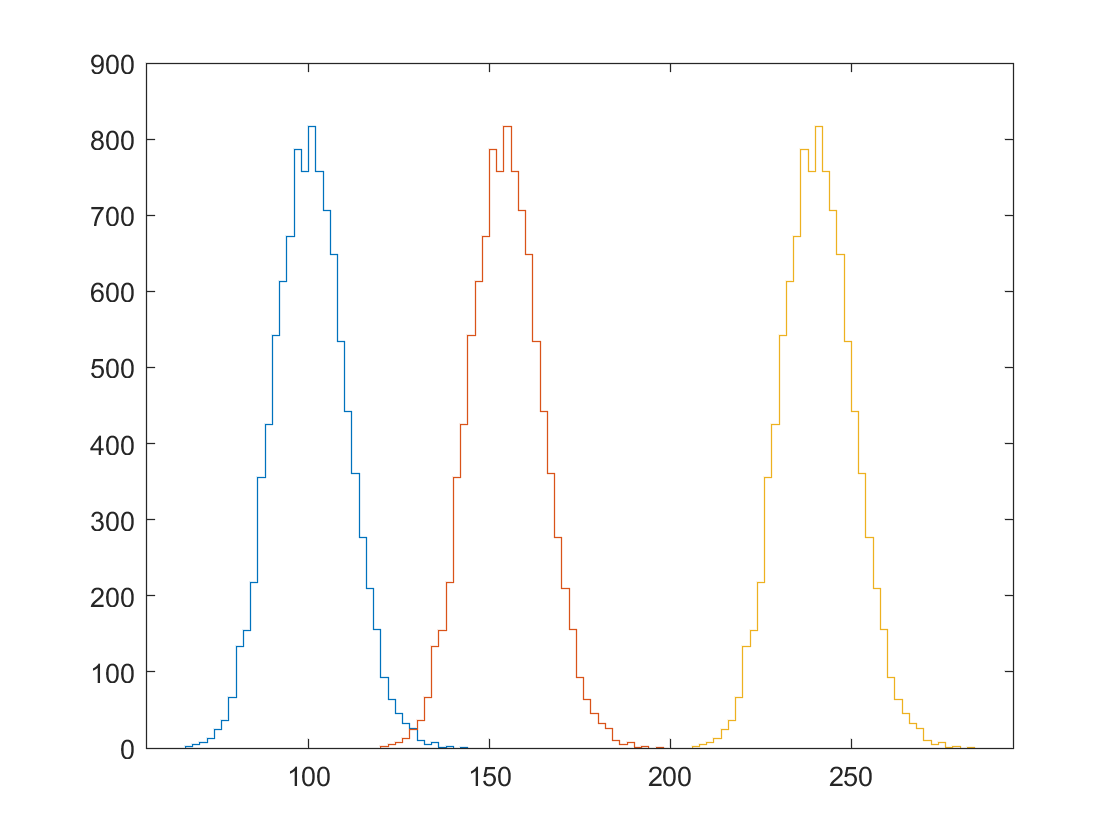

bpoints = poissrnd(100,[1 10000]);
histogram(bpoints,'DisplayStyle',"stairs")
hold on

signal5 = zeros(1,10000);
for i = 1:length(signal5)
    signal5(i) = signal_5 - 100;
end

bplus5 = bpoints+signal5;
histogram(bplus5,'DisplayStyle',"stairs")

signal = zeros(1,10000);
for i = 1:length(signal)
    signal(i) = 140;
end

bplus140 = bpoints+signal;
histogram(bplus140,'DisplayStyle','stairs')
xlabel('Observed Signal')
ylabel('Counts')
title('Background and Signal Histograms')
legend('Background','Signal = 154','Signal = 240')
hold off

b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

**Problem 3**

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more).

a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed data

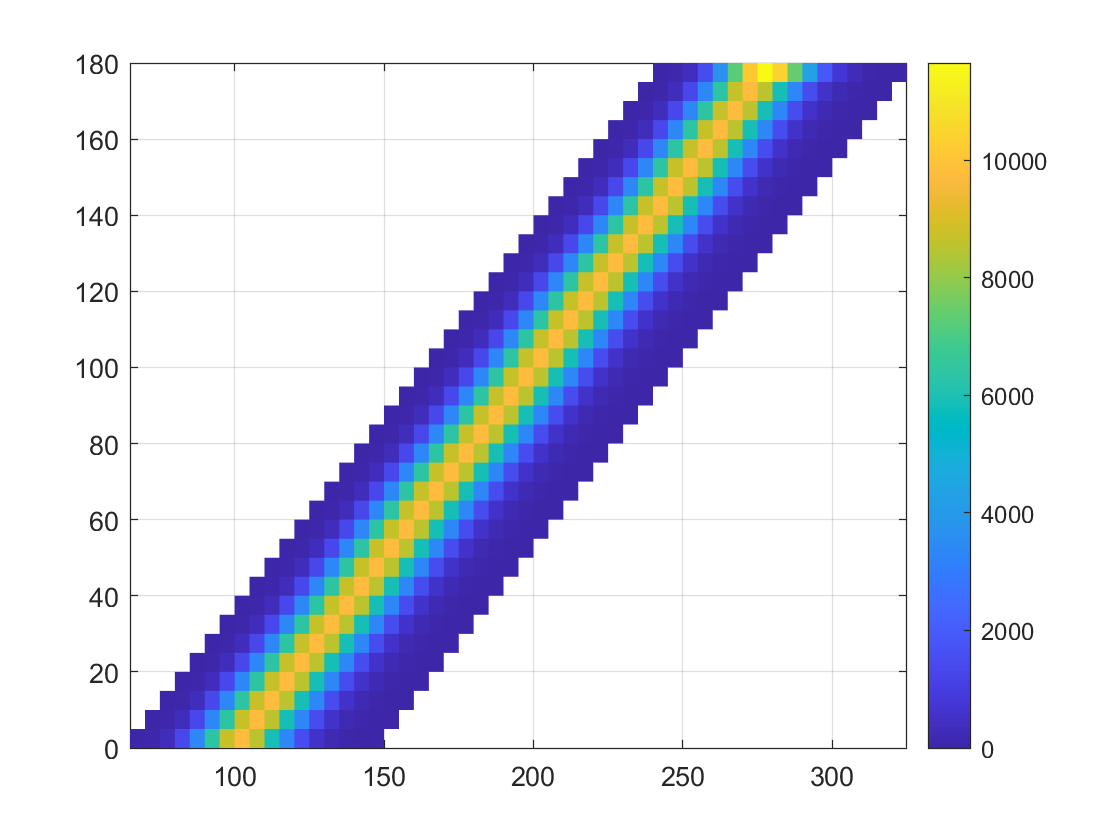

signal = zeros(180,10000);

for n = 0:length(signal(:,1))
    for i = 1:length(signal(1,:))
        signal(n+1,i) = n;
    end
end

truesignal = 1:n;
added = bpoints+signal;
histogram2(added,signal,"DisplayStyle",'tile','EdgeColor','none')
colorbar

xlabel('Observed Signal')
ylabel("True Signal")
title('True vs. Observed Signal')

b) For the same injected signal power as in problem 2, show that you get the same answer.

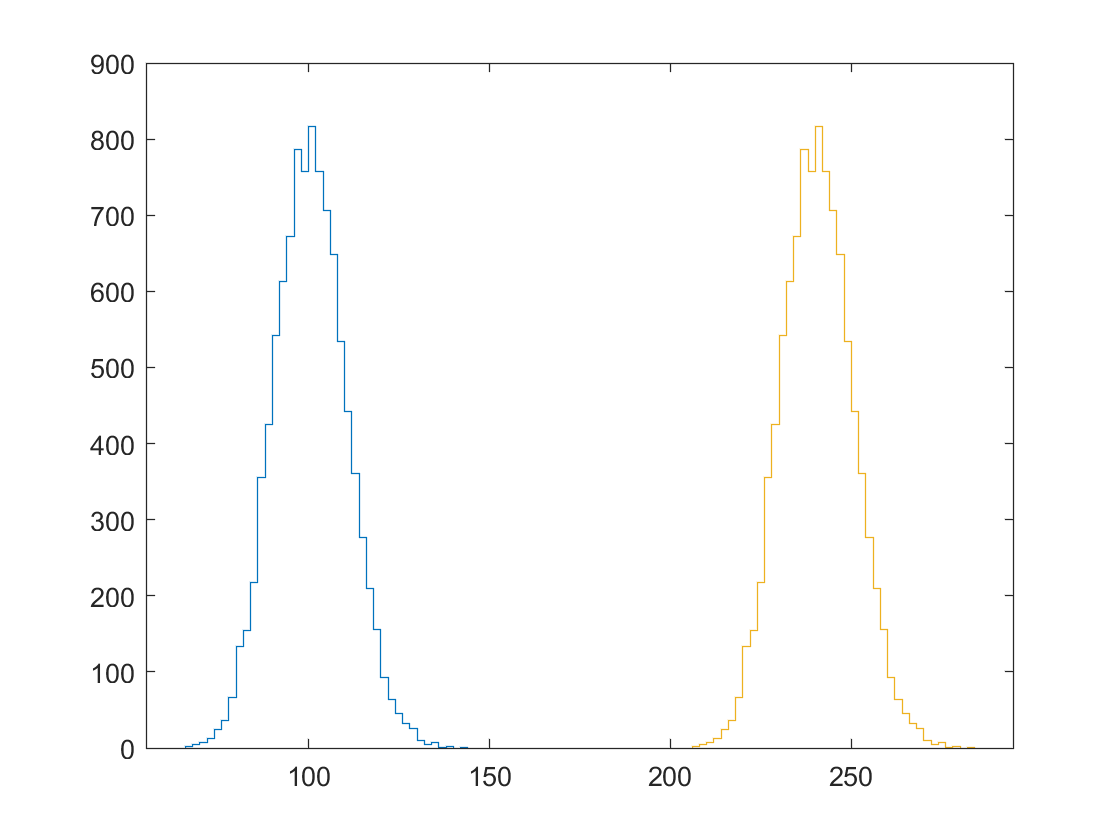

sig = 240;
histogram(bpoints,'DisplayStyle',"stairs")
hold on 
histogram(bplus140,'DisplayStyle',"stairs")
histogram(added(141,:),'DisplayStyle',"stairs")
xlabel('Observed Signal')
ylabel('Counts')
title('Background and Signal Histograms')
legend('Background','Problem 2 240','Signal = 240')
hold off

c) Now reverse the problem, select an observed data value (pick something quite a bit stronger than 5σ) and create a 1D histogram of the true signal probability given the observed data. Describe the meaning of this histogram.

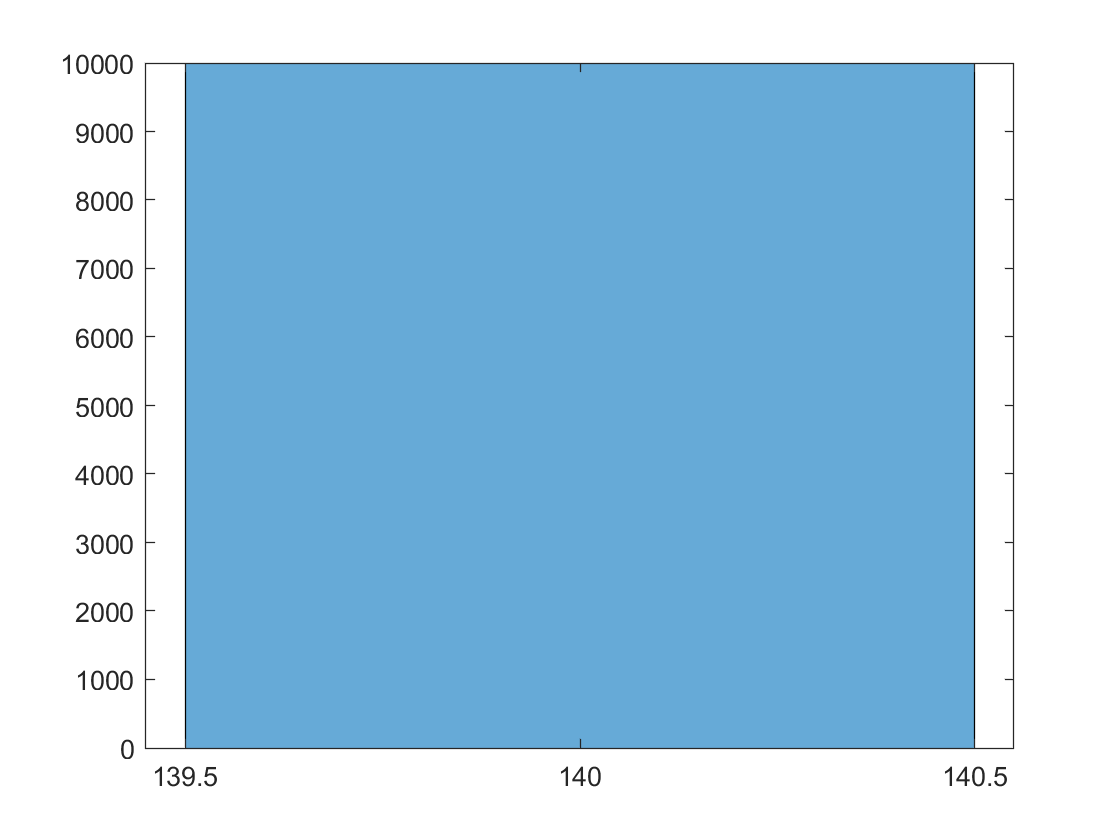

Observed = 141;
histogram(signal(141,:))

d) For your observed signal, what is the 1σσ uncertainty on the true signal strength?

e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?